# Reto F3001C

Max Eduardo Garcia Esquivel - A01236070.

Convinaciones con condicion:

    Wg 1 - Modo 14, Modo 15

    Wg 3 - Modo 15

   %Code Variables
%Sizes
sXs = [1000,930,475,405];
sYs = [325,235,955,730];

%Paths
SuperiorPath = "./../Phase4V2/Sweeps/Matlab/";
FundamentalPath = "./../Phase3/Sweeps/Matlab/";

%Modes
Superior = "Waveguide%i_%i_532_Mode%i";
Fundamental = "Waveguide%i_%i_1596";
ModesSup = [15,9,19,12];

warning('off','MATLAB:polyfit:RepeatedPointsOrRescale')

## Waveguide selector:

sel = 1;
nmodes = ModesSup(sel);
mode = 14;
disp("Selected waveguide:")

Selected waveguide:


disp("   Size: "+num2str(sXs(sel))+"x"+num2str(sYs(sel)));

   Size: 1000x325


disp("   Mode: "+num2str(mode));

   Mode: 14


 

file = sprintf(Fundamental,sXs(sel)*1000,sYs(sel)*1000);
load(FundamentalPath+file);
wgFundamental = waveguide(lambda,neff);
file = sprintf(Superior,sXs(sel),sYs(sel),mode);
load(SuperiorPath+file);
wgSuperior = waveguide(lambda,neff);

lphLim = [min(wgFundamental.lambdaData) max(wgFundamental.lambdaData)];
lpLim = [min(wgSuperior.lambdaData) max(wgSuperior.lambdaData)];
lpm = lpLim(1);
lpM = lpLim(2);

## Phase Matching

size=50;

dW = 1e8;

wn = linspace(2.*pi.*3.*10.^8/lphLim(1),2.*pi.*3.*10.^8/lphLim(2),6);

disp("Pump wavelength: "+num2str(lpLim(1))+"-"+num2str(lpLim(2)));

Pump wavelength: 0.51-0.532


disp("Photon wavelength: "+num2str(lphLim(1))+"-"+num2str(lphLim(2)));

Photon wavelength: 1.53-1.596


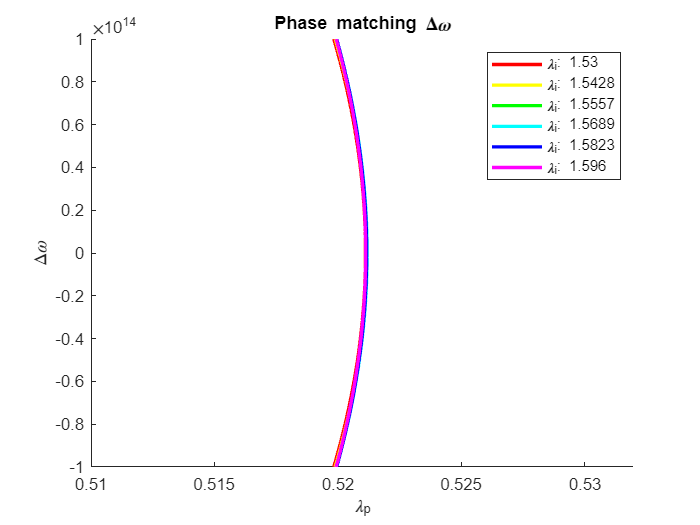

wp = linspace(2.*pi.*3.*10.^8./lpLim(1),2.*pi.*3.*10.^8./lpLim(2),size);
dw = linspace(dW,-dW,size);
[WP,DW] = meshgrid(wp,dw);

figure
hold on
leg = {};
for n = 1:6
    wi = wn(n);
    wr = DW+(WP-wi)/2;
    ws = WP-wi-wr;
    DK = wgSuperior.kwFun(WP)-(wgFundamental.kwFun(wi)+wgFundamental.kwFun(wr)+wgFundamental.kwFun(ws));
    switch n
        case 1
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'r','LineWidth',2);
        case 2
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'y','LineWidth',2);
        case 3
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'g','LineWidth',2);
        case 4
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'c','LineWidth',2);
        case 5
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'b','LineWidth',2);
        case 6
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'m','LineWidth',2);
    end

    leg(end+1) = {"\lambda_i: "+num2str(2.*pi.*3.*10.^8/wi)};
end

xlabel("\lambda_p");
ylabel("\Delta\omega");
title("Phase matching \Delta\omega")

legend(leg)

## Phase Matching (Zoomed)

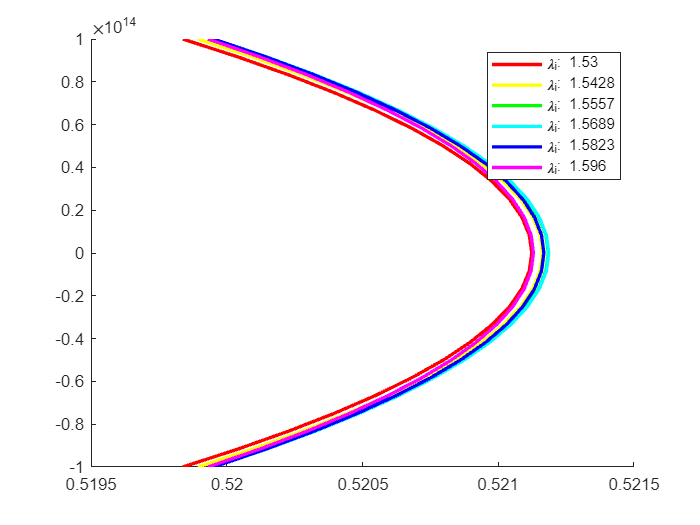

minl = 0.5195;
maxl = 0.5215;

size=25;

dW = 100000000;

wp = linspace(2.*pi.*3.*10.^8./(minl),2.*pi.*3.*10.^8./(maxl),size);
dw = linspace(dW,-dW,size);
[WP,DW] = meshgrid(wp,dw);

figure
hold on
leg = {};
for n = 1:6
    wi = wn(n);
    wr = DW+(WP-wi)/2;
    ws = WP-wi-wr;
    DK = wgSuperior.kwFun(WP)-(wgFundamental.kwFun(wi)+wgFundamental.kwFun(wr)+wgFundamental.kwFun(ws));
    switch n
        case 1
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'r','LineWidth',2);
        case 2
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'y','LineWidth',2);
        case 3
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'g','LineWidth',2);
        case 4
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'c','LineWidth',2);
        case 5
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'b','LineWidth',2);
        case 6
            contour(2.*pi.*3.*10.^8./wp,dw.*10^6,DK,[0 0],'m','LineWidth',2);
    end

    leg(end+1) = {"\lambda_i: "+num2str(2.*pi.*3.*10.^8/wi)};
end

legend(leg)

## Comprobation of Δk=0 at degenerancy

size=50;

lp = linspace(lpLim(1),lpLim(2),size);
wp = 2.*pi.*3.*10.^8./lp;
ws = wp./3;
leg = {};

figure
hold on

dk0s = [];

dk = wgSuperior.kwFun(wp)-(3*wgFundamental.kwFun(ws));

if(min(dk)<=0 && max(dk)>=0)
    dk0s = [dk0s i];
end

plot(lp,dk);
leg(end+1) = {"Mode"'+num2str(mode)};

if ~isequal(dk0s,[])
    strDk0s = "Modo con dK=0";
else
    strDk0s = "Modo sin dK=0";
end

disp(strDk0s)

Modo con dK=0


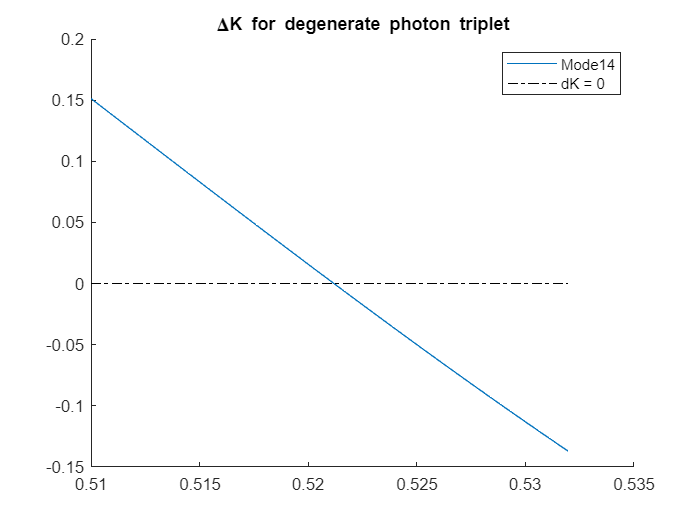


plot([lpLim(1),lpLim(2)],[0,0],'k-.')
leg(end+1) = {"dK = 0"};

legend(leg);
title("\DeltaK for degenerate photon triplet");

## Obtain wavelengths for energy and momentum conservation

definition = 0.000001

definition = 1.0000e-06


lphLim = [min(wgFundamental.lambdaData) max(wgFundamental.lambdaData)];
lpLim = [min(wgSuperior.lambdaData) max(wgSuperior.lambdaData)];
lp = [lpLim(1):definition:lpLim(2)];
wp = 2.*pi.*3.*10.^8./lp;
ws = wp./3;
leg = {};

figure
hold on

dk0s = [];

dk = wgSuperior.kwFun(wp)-(3*wgFundamental.kwFun(ws));

ind = find(min(abs(dk))==abs(dk));
disp("Value with dk=0, Pump: w="+num2str(wp(ind))+", l="+num2str(lp(ind))+", dk="+num2str(dk(ind)));

Value with dk=0, Pump: w=3616651941.6293, l=0.52119, dk=-3.8399e-06


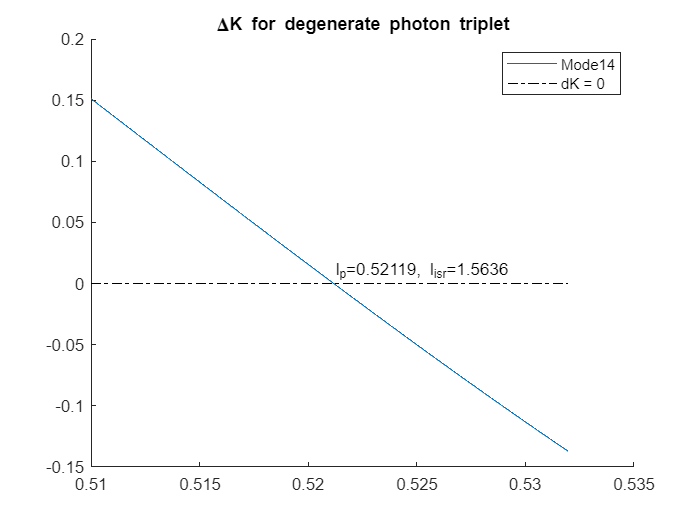


phlp = lp(ind);
phlph = lp(ind)*3;

plot(lp,dk);
leg(end+1) = {"Mode"'+num2str(mode)};

plot([lpLim(1),lpLim(2)],[0,0],'k-.');
leg(end+1) = {"dK = 0"};

text(lp(ind),dk(ind)+0.01,"l_p="+num2str(lp(ind))+", l_{isr}="+num2str(lp(ind)*3));

legend(leg);
title("\DeltaK for degenerate photon triplet");

## Data for photons

Wg1, M14: lp = 0.52119, lisr=1.56357.

Wg1, M15: lp = 0.51189, lisr=1.53567.

Wg3, M15: lp = 0.51971, lisr=1.55913.

## Phase Matching Function


$$\phi \left(\omega_r ,\omega_s ,\omega_i \right)=\textrm{sinc}\left\lbrack L\frac{\Delta k\left(\omega_r ,\omega_s ,\omega_i \right)}{2}\right\rbrack \exp \left\lbrack \textrm{iL}\frac{\Delta k\left(\omega_r ,\omega_s ,\omega_i \right)}{2}\right\rbrack$$



$$\Delta k\left(\omega_r ,\omega_s ,\omega_i \right)=k_p \left(\omega_r +\omega_s +\omega_i \right)-k_r \left(\omega_r \right)-k_s \left(\omega_s \right)-k_i \left(\omega_i \right)-\Phi_{\textrm{NL}}$$


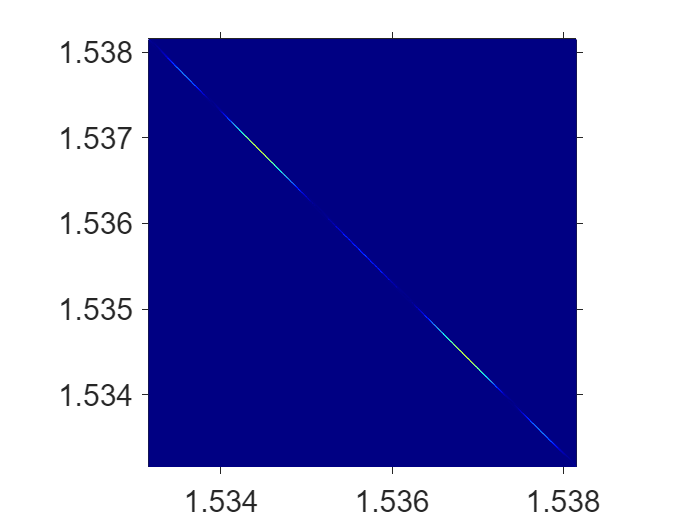

size = 400;

phwph = (2*pi*3*10^8)/phlph;
dw = 4.8e6;%(2*pi*3*10^8)*/phwph-1/(phwph+0.006));
dw = 1e8


% Linear vectors
wph = linspace(phwph-dw,phwph+dw,size);
mwph = phwph;
[WPHX,WPHY] = meshgrid(wph,wph);

sigma = 0.01e12;
lp0 = phlp;
wp0 = 2*pi*3*10^8/lp0;

L = 0.2e6;

L = L/600;
sigma = sigma*400;

ca = 2^(1/4)/(pi^(1/4)*sigma);
wpw0 = (WPHX+WPHY+mwph-wp0)*10^6;
awp = ca*exp(-(wpw0).^2/sigma^2);

dkrsi = wgSuperior.kwFun(WPHX+WPHY+mwph)-wgFundamental.kwFun(WPHX)-wgFundamental.kwFun(WPHY)-wgFundamental.kwFun(mwph)+PNL;
sinPh = sinc(L*dkrsi/2);
expPh = exp(1i*L*dkrsi/2);
fpm = sinPh.*expPh;

JSI = awp.*fpm;

figure
pcolor((2*pi*3*10^8)./wph,(2*pi*3*10^8)./wph,abs(awp).^2), shading interp
title("a(wp)")
colormap(jet);
figure
pcolor((2*pi*3*10^8)./wph,(2*pi*3*10^8)./wph,abs(fpm).^2), shading interp
title("phi(wp)")
colormap(jet);
figure
pcolor((2*pi*3*10^8)./wph,(2*pi*3*10^8)./wph,abs(JSI).^2), shading interp
title("JSI")
colormap(jet);

size = 401;
dl = 0.0025;
cw = 2*pi*3*10^8;

% Linear vectors
lph = linspace(phlph-dl,phlph+dl,size);
wph = (2*pi*3*10^8)./lph;
mlph = phlph;
mwph = (2*pi*3*10^8)./mlph;
[WPHX,WPHY] = meshgrid(wph,wph);

L = 1;

PNL = 0;
dkrsi = wgSuperior.kwFun(WPHX+WPHY+mwph)-wgFundamental.kwFun(WPHX)-wgFundamental.kwFun(WPHY)-wgFundamental.kwFun(mwph)+PNL;
fpm = sinc(L.*dkrsi./2).*exp(1i*L.*dkrsi./2);

figure
%surf(WPHX,WPHY,WPHX.*0+mwph,'cdata',abs(fpm).^2), shading interp
%surf(WPHX.*0,WPHX,WPHY,'cdata',abs(fpm).^2), shading interp
pcolor(lph,lph,abs(fpm).^2), shading interp
colormap(jet);
%alfa(0.5)
set(gcf,'Color',[1,1,1]);
set(gca,'TickDir','out','TickLength',[0.015 0.015]);
set(gca,'FontSize',18,'FontName','arial');
box on
axis square

## Pump Spectral Amplitude Function


$$\alpha \left(\omega_p \right)=\frac{2^{\frac{1}{4}} }{\pi^{\frac{1}{4}} \sqrt{\sigma \;}}e^{-\frac{{\left(\omega_p -\omega_{\textrm{p0}} \right)}^2 }{\sigma^2 }}$$


size = 100;

dl = 0.1;

sigma = 0.1e8;
dw = 24e12;
l0 = phlp;
w0 = 2*pi*3*10^8/l0;

lph = linspace(phlph-dl,phlph+dl,size);
wph = (2*pi*3*10^8)./lph;
mlph = phlph;
mwph = (2*pi*3*10^8)./mlph;
[WPHX,WPHY] = meshgrid(wph,wph);

L = 1e12;

awp = (2^(1/4))/(pi^(1/4)*sqrt(sigma))*exp(-((WPHX+WPHY+mwph-w0).^2)/(sigma.^2));

pcolor(lph,lph,abs(awp).^2), shading interp
colormap(jet);
set(gcf,'Color',[1,1,1]);
set(gca,'TickDir','out','TickLength',[0.015 0.015]);
set(gca,'FontSize',18,'FontName','arial');
box on
axis square

## Jopint Spectral Intensity (JSI)


$$F\left(\omega_r ,\omega_s ,\omega_i \right)=\alpha \left(\omega_r +\omega_s +\omega_i \right)\phi \left(\omega_r ,\omega_s ,\omega_i \right)$$


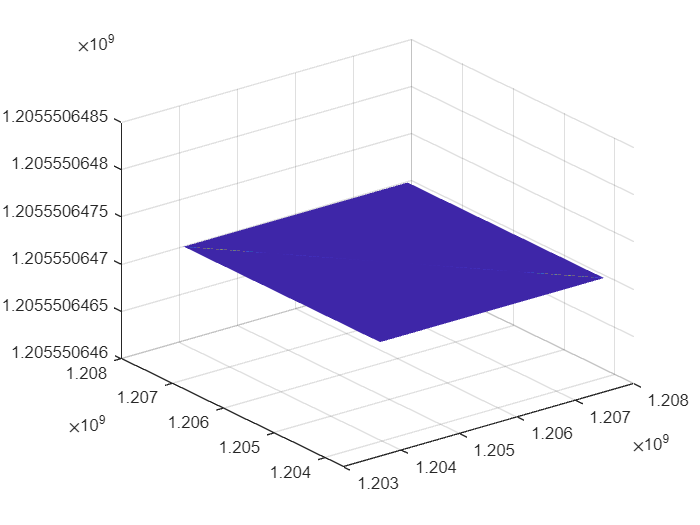

size = 400;
dl = 0.0025;

% Linear vectors
lph = linspace(phlph-dl,phlph+dl,size);
wph = (2*pi*3*10^8)./lph;
mlph = phlph;
mwph = (2*pi*3*10^8)./mlph;
[WPHX,WPHY] = meshgrid(wph,wph);

L = 1e6;

size = 100;

dl = 0.1;

sigma = 0.1e8;
dw = 24e12;
l0 = phlp;
w0 = 2*pi*3*10^8/l0;

awp = (2^(1/4))/(pi^(1/4)*sqrt(sigma))*exp(-((WPHX+WPHY+mwph-w0).^2)/(sigma.^2));

PNL = 0;

JSI = ((2^(1/4))/(pi^(1/4)*sqrt(sigma))*exp(-((WPHX+WPHY+mwph-w0).^2)/(sigma.^2))).*...
    (sinc(L.*(wgSuperior.kwFun(WPHX+WPHY+mwph)-wgFundamental.kwFun(WPHX)-wgFundamental.kwFun(WPHY)-wgFundamental.kwFun(mwph)+PNL)./2).*...
    exp(1i*L.*(wgSuperior.kwFun(WPHX+WPHY+mwph)-wgFundamental.kwFun(WPHX)-wgFundamental.kwFun(WPHY)-wgFundamental.kwFun(mwph)+PNL)./2));

figure
pcolor(lph,lph,abs(JSI).^2), shading interp
surf(WPHX,WPHY,WPHX.*0+mwph,'cdata',abs(JSI).^2), shading interp

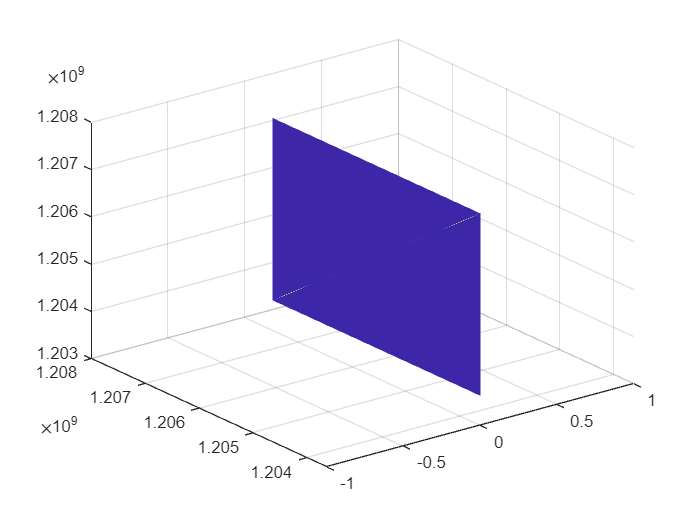

surf(WPHX.*0,WPHX,WPHY,'cdata',abs(fpm).^2), shading interp

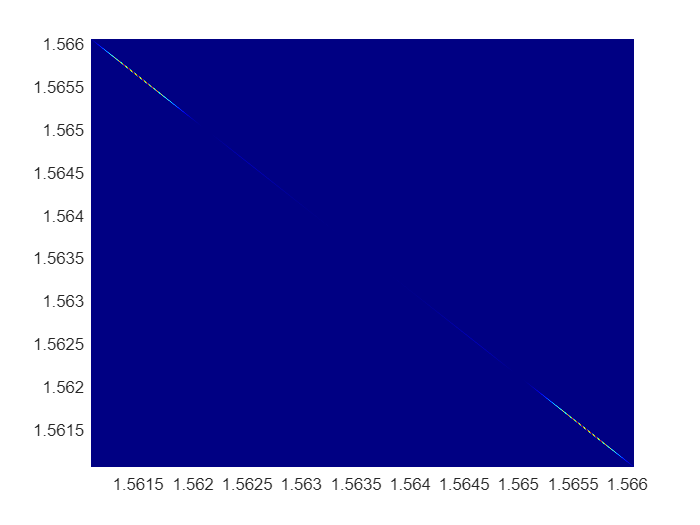

pcolor(lph,lph,abs(fpm).^2), shading interp
colormap(jet);

alfa(0.5)

Unrecognized function or variable 'alfa'.

set(gcf,'Color',[1,1,1]);
set(gca,'TickDir','out','TickLength',[0.015 0.015]);
set(gca,'FontSize',18,'FontName','arial');
box on
axis square


$$\nu +=\frac{1}{\sqrt{3}}\left(\omega_r +\omega_r +\omega_r -{3\omega }_0 \right)$$
